Right, so, firstly, using Poiseuille's law, $Q=\frac{\Delta p\pi D^4 }{128\mu \;L}$.

Secondly, ideal gas equation $\textrm{PV}=\textrm{mRT}$.

The volume of the cylinder changes as a function of time. Being a single-inlet system, the mass is also a function of time and the system is transient.

So, let $V\left(t\right)$ and $m\left(t\right)$be a function of time and the process be isothermal, then pressure inside the cylinder is given by ideal gas equation $P\left(t\right)=m\left(t\right)\frac{\textrm{RT}}{V\left(t\right)}$.

Identifying the system as a single inlet no outlet system, we obtain $Q=\frac{\textrm{dm}}{\textrm{dt}}$.

So, $\frac{\textrm{dm}}{\textrm{dt}}=\frac{\pi D^4 }{128\mu \;L}\cdot \left(P_{\textrm{atm}} -\frac{m\left(t\right)}{V\left(t\right)}\textrm{RT}\right)$.

Here, $V\left(t\right)$is defined function of time.

Assume atmospheric conditions.

atm=101325;
R=8314/28;
T=298;
D=0.01;
mu=1.81e-5;
L=0.1;

Load up the symbolic lab.

syms t m1(t) m2(t) V(t) V1(t) V2(t)
% V(t)=0.1 + 0.9/6*t*(1-heaviside(t-6))+0.9*heaviside(t-6)]
V1(t)= 0.1 + 0.9/6*t;
V2(t)= 1;
Dm1=diff(m1);
Dm2 = diff(m2);

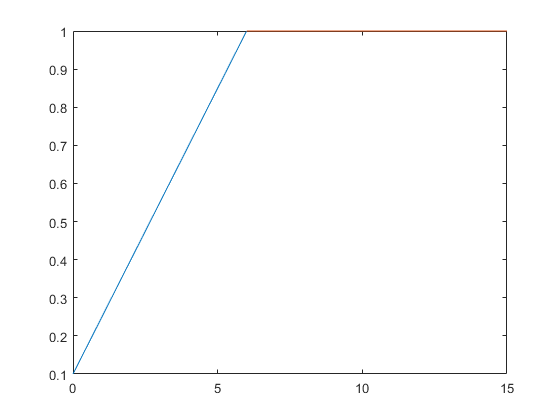

figure(1)
clf
fplot(V1,[0,6])
hold on
fplot(V2,[6,15])

Setup the equation.

eqn1 = Dm1-pi*D.^4/128/mu/L * (atm - m1*R*T/V1) == 0

$$eqn1(t) = \frac{\partial }{\partial t}m_{1}\left(t\right)+\frac{\pi \,\left(\frac{619393\,m_{1}\left(t\right)}{7\,\left(\frac{3\,t}{20}+\frac{1}{10}\right)}-101325\right)}{23168}=0$$

eqn2 = Dm2-pi*D.^4/128/mu/L * (atm - m2*R*T/V2) == 0

$$eqn2(t) = \frac{\partial }{\partial t}m_{2}\left(t\right)+\frac{\pi \,\left(\frac{619393\,m_{2}\left(t\right)}{7}-101325\right)}{23168}=0$$

Boundary conditions.

cond1 = m1(0) == atm*V1(0)/R/T

$$cond1 = m_{1}\left(0\right)=\frac{141855}{1238786}$$

cond2 = m2(6) == m1(6)

$$cond2 = m_{2}\left(6\right)=m_{1}\left(6\right)$$

Hit it: solve the equation.

[solm1, solm2] = dsolve([eqn1,eqn2],[cond1, cond2])

$$solm1 = \frac{8627053680\,{\left(\frac{2}{3}\right)}^{\frac{3096965\,\pi }{121632}}}{619393\,\left(3096965\,\pi +121632\right)\,{\left(t+\frac{2}{3}\right)}^{\frac{3096965\,\pi }{121632}}}+\frac{101325\,\pi \,{\left(t+\frac{2}{3}\right)}^{\frac{3096965\,\pi }{121632}+1}}{23168\,\left(\frac{3096965\,\pi }{121632}+1\right)\,{\left(t+\frac{2}{3}\right)}^{\frac{3096965\,\pi }{121632}}}$$

$$solm2 = {\mathrm{e}}^{-\frac{619393\,\pi \,t}{162176}}\,\left(\frac{709275\,{\mathrm{e}}^{\frac{619393\,\pi \,t}{162176}}}{619393}+\frac{8627053680\,{\mathrm{e}}^{\frac{1858179\,\pi }{81088}}\,\left({\left(\frac{2}{3}\right)}^{\frac{3096965\,\pi }{121632}}-10\,{\left(\frac{20}{3}\right)}^{\frac{3096965\,\pi }{121632}}\right)}{619393\,{\left(\frac{20}{3}\right)}^{\frac{3096965\,\pi }{121632}}\,\left(3096965\,\pi +121632\right)}\right)$$

The plotting section.

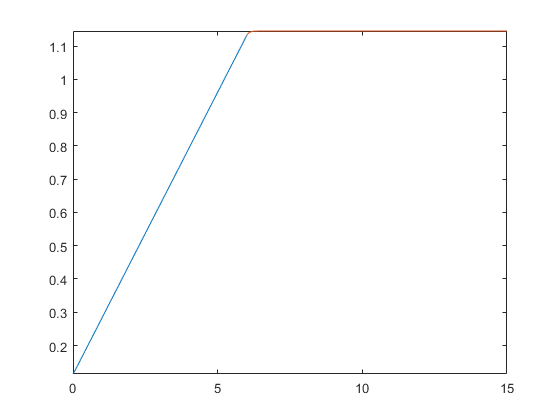

figure(2)
clf
fplot(solm1,[0,6])
hold on
fplot(solm2,[6,15])